%data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features_v1.csv', 'ReadVariableNames',1);
data = readtable('Datasets/Features_v1.csv', 'ReadVariableNames',1);

GD = data.GoodDays; 
MD = data.ModerateDays;
UFSGD = data.UnhealthyForSensitiveGroupsDays;
UD = data.UnhealthyDays;
VUD = data.VeryUnhealthyDays;
HD = data.HazardousDays;

edges = [0:0.025:1];
edgesN = [-1:0.025:1];

%GD 
minGD = min(GD)

minGD = 0.1004

maxGD = max(GD)

maxGD = 0.9986

nnzGD = nnz(GD)

nnzGD = 832

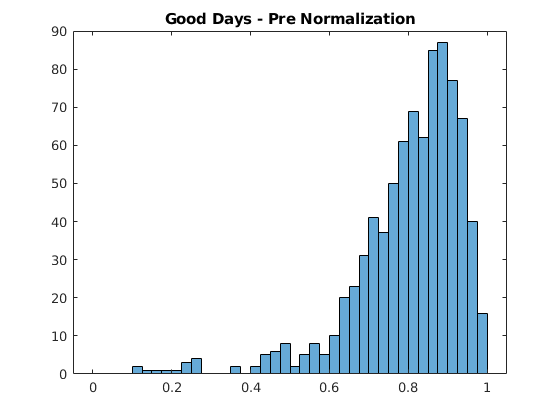


histogram(GD, edges)
title('Good Days - Pre Normalization')

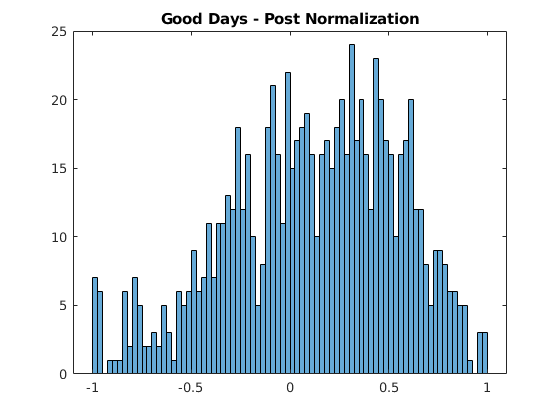


GDN = 2.*(GD).^3-1;
histogram(GDN, edgesN)
title('Good Days - Post Normalization')

%MD 
minMD = min(MD)

minMD = 0.0014

maxMD = max(MD)

maxMD = 0.7120

nnzMD = nnz(MD) 

nnzMD = 832

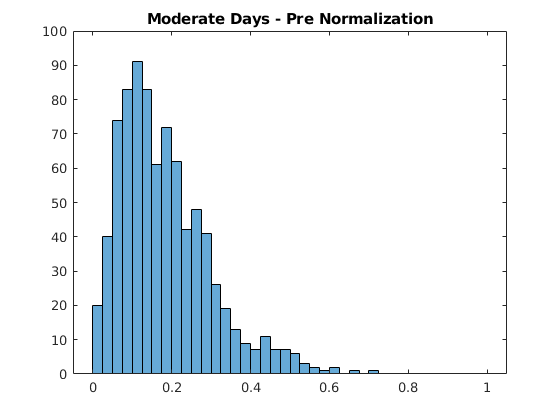


histogram(MD, edges)
title('Moderate Days - Pre Normalization')

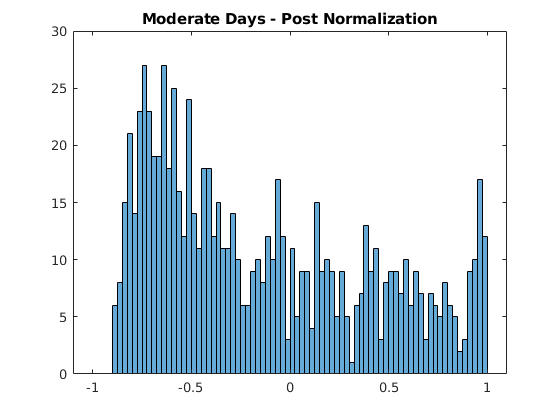


nnzMD_V = MD(MD~=0);
medMD_V = median(nnzMD_V);

MDN = tanh(7*(MD-0.2));
histogram(MDN, edgesN)
title('Moderate Days - Post Normalization')

%UFSGD
minUFSGD = min(UFSGD)

minUFSGD = 0

maxUFSGD = max(UFSGD)

maxUFSGD = 0.2822

nnzUFSGD = nnz(UFSGD)

nnzUFSGD = 756

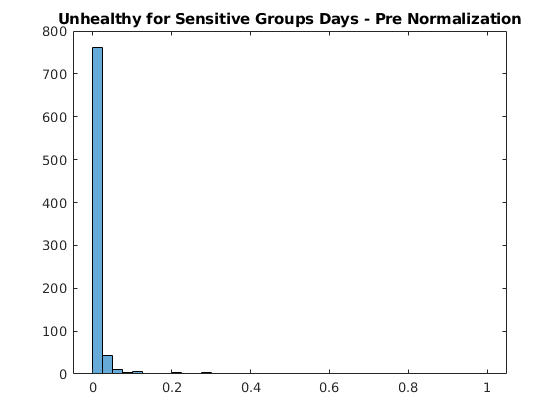


histogram(UFSGD, edges)
title('Unhealthy for Sensitive Groups Days - Pre Normalization')

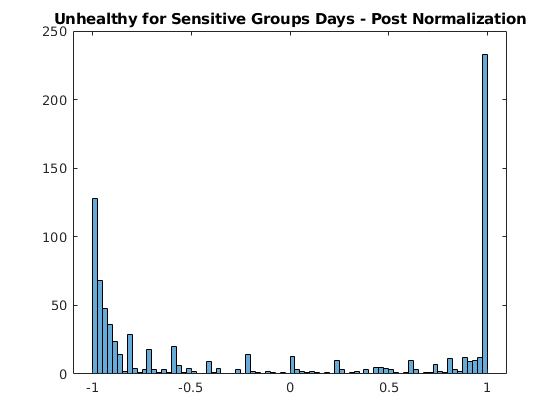


nnzUFSGD_V = UFSGD(UFSGD~=0);
medUFSGD_V = median(nnzUFSGD_V);

UFSGDN = tanh(500*(UFSGD-0.005));
histogram(UFSGDN, edgesN)
title('Unhealthy for Sensitive Groups Days - Post Normalization')

%UD
minUD = min(UD)

minUD = 0

maxUD = max(UD)

maxUD = 0.3305

nnzUD = nnz(UD)

nnzUD = 351

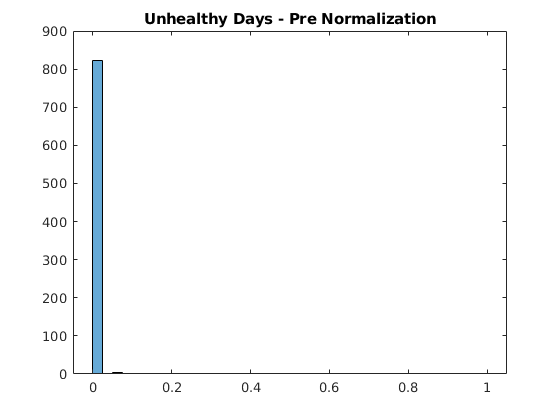


histogram(UD, edges)
title('Unhealthy Days - Pre Normalization')

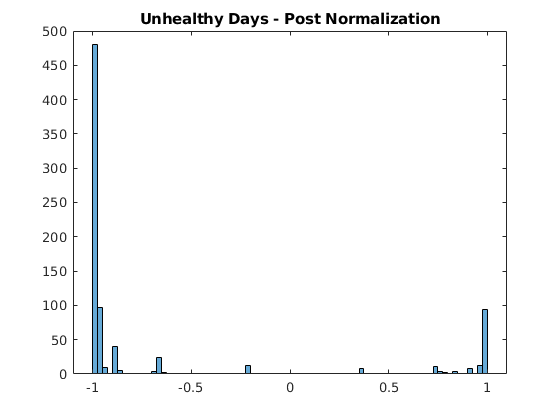


nnzUD_V = UD(UD~=0);
medUD_V = median(nnzUD_V);

UDN = tanh(1300*(UD-0.002));
histogram(UDN,edgesN)
title('Unhealthy Days - Post Normalization')

%VUD
minVUD = min(VUD)

minVUD = 0

maxVUD = max(VUD)

maxVUD = 0.0256

nnzVUD = nnz(VUD)

nnzVUD = 79

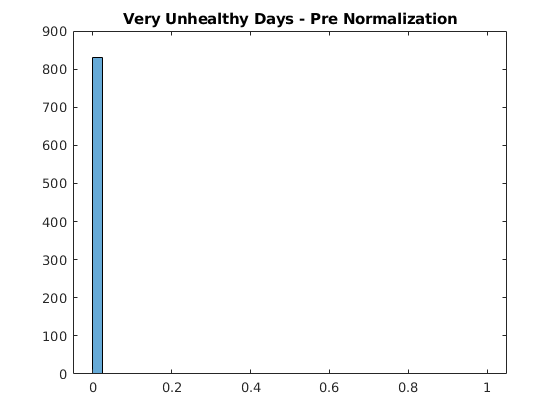


histogram(VUD, edges)
title('Very Unhealthy Days - Pre Normalization')

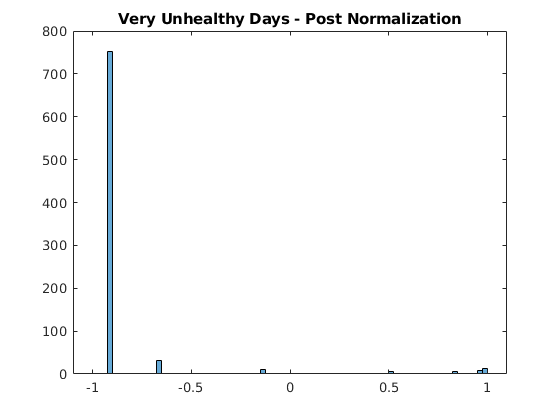


nnzVUD_V = VUD(VUD~=0);
medVUD_V = median(nnzVUD_V);

VUDN = tanh(1500*(VUD-0.001));
histogram(VUDN,edgesN)
title('Very Unhealthy Days - Post Normalization')

%HD
minHD = min(HD)

minHD = 0

maxHD = max(HD)

maxHD = 0.0310

nnzHD = nnz(HD)

nnzHD = 34

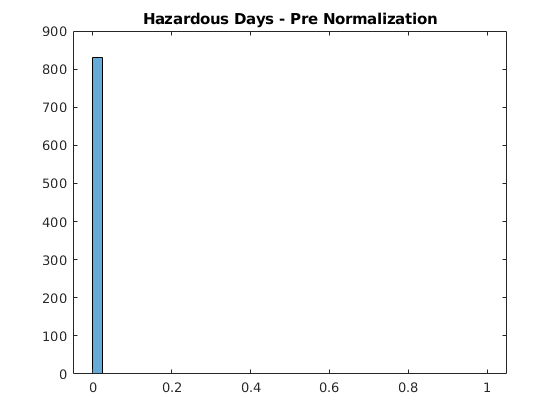


histogram(HD, edges)
title('Hazardous Days - Pre Normalization')

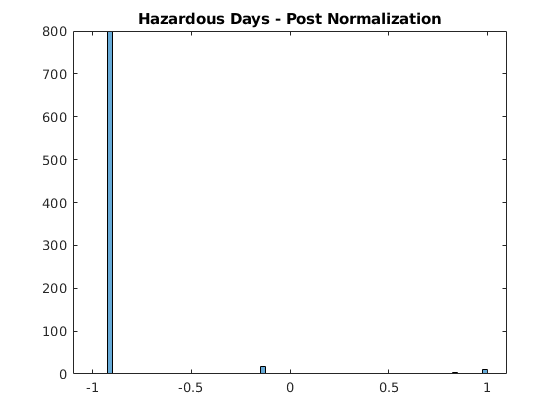


nnzHD_V = HD(HD~=0);
medHD_V = median(nnzHD_V);

HDN = tanh(3000*(HD-0.0005));
histogram(HDN, edgesN)
title('Hazardous Days - Post Normalization')

NormMat = [GDN MDN UFSGDN UDN VUDN HDN];
[t_RND, C_RND] = kmeans(NormMat, 3)

t_RND =      1
     1
     1
     3
     1
     3
     2
     3
     2
     1


C_RND =     0.5067   -0.6202   -0.8210   -0.9213   -0.8934   -0.8979
   -0.0656    0.1424   -0.6472   -0.9677   -0.9036   -0.9051
   -0.1557    0.1821    0.8948   -0.1535   -0.6928   -0.7878


RD = [GD MD UFSGD UD VUD HD];
mN_RD = normalize(RD, 'range', [-1,1])

mN_RD =     0.7284   -0.6636   -0.9827   -1.0000   -1.0000   -1.0000
    0.8161   -0.7692   -0.9958   -1.0000   -1.0000   -1.0000
    0.7577   -0.6964   -0.9934   -1.0000   -1.0000   -1.0000
    0.3076   -0.1458   -0.9737   -0.9772   -1.0000   -1.0000
    0.8042   -0.7542   -0.9958   -1.0000   -1.0000   -1.0000
   -0.1789    0.4284   -0.8512   -0.9945   -1.0000   -1.0000
    0.5932   -0.4885   -0.9932   -1.0000   -1.0000   -1.0000
    0.4927   -0.3803   -0.9459   -1.0000   -1.0000   -1.0000
    0.1836    0.0226   -0.9834   -0.9972   -0.9623   -1.0000
    0.6490   -0.5589   -0.9935   -1.0000   -1.0000   -1.0000


%[t_RD, C_RD] = kmeans(RD, 4)

RND_C1 = RD(t_RND ==1,:)

RND_C1 =     0.8766    0.1210    0.0024         0         0         0
    0.9160    0.0834    0.0006         0         0         0
    0.8898    0.1093    0.0009         0         0         0
    0.9106    0.0888    0.0006         0         0         0
    0.8409    0.1581    0.0009         0         0         0
    0.9092    0.0902    0.0005         0         0         0
    0.9954    0.0046         0         0         0         0
    0.9695    0.0300    0.0005         0         0         0
    0.9670    0.0330         0         0         0         0
    0.9397    0.0603         0         0         0         0


RND_C2 = RD(t_RND ==2,:)

RND_C2 =     0.8159    0.1831    0.0010         0         0         0
    0.6320    0.3648    0.0023    0.0005    0.0005         0
    0.7214    0.2770    0.0016         0         0         0
    0.7099    0.2891    0.0010         0         0         0
    0.7234    0.2725    0.0041         0         0         0
    0.7875    0.2098    0.0027         0         0         0
    0.8202    0.1757    0.0037    0.0005         0         0
    0.6673    0.3300    0.0027         0         0         0
    0.8160    0.1840         0         0         0         0
    0.7768    0.2187    0.0041    0.0005         0         0


RND_C3 = RD(t_RND ==3,:)

RND_C3 =     0.6876    0.3049    0.0037    0.0038         0         0
    0.4692    0.5089    0.0210    0.0009         0         0
    0.7708    0.2216    0.0076         0         0         0
    0.8691    0.1207    0.0102         0         0         0
    0.7341    0.2599    0.0060         0         0         0
    0.2670    0.4149    0.2665    0.0516         0         0
    0.7716    0.2223    0.0060         0         0         0
    0.1625    0.7120    0.1182    0.0050    0.0023         0
    0.5628    0.4245    0.0128         0         0         0
    0.2342    0.6116    0.1132    0.0183    0.0050    0.0178


%RND_C4 = RD(t_RND ==4,:)
